close("all"); clear; clc;

A = [
    -1,-4;
    4,-1
    ];

b = 0.05;

ns = 100;
ts = 0.02;
tf = ns*ts;
t = linspace(0,tf,ns + 1);

X0 = zonotope2d(0.1.*eye(2),[1;0]);

R = girard2005Alg(X0,A,b,t);

sys = ss(A,[0;0],eye(2),0);
traj = @(x0)lsim(sys,0.*t,t,x0);
trajx = @(x0)traj(x0)*[1;0];
trajy = @(x0)traj(x0)*[0;1];
plotTraj = @(x0)plot(trajx(x0),trajy(x0),"k:", ...
    "LineWidth",2 ...
    );

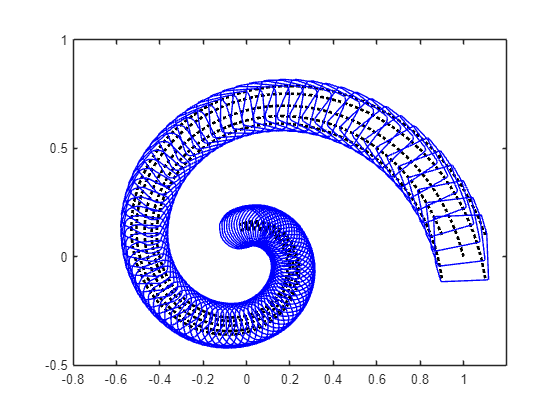

fig = figure();
axe = axes(fig);
% X0.plot();
hold(axe,"on");

x0 = [1,0;
    0.9,-0.1,;
    1.1,-0.1;
    0.9,0.1;
    1.1,0.1,
    ].';

cellfun(plotTraj,num2cell(x0,1));
hold(axe,"off");
arrayfun(@plot,R);
axis(axe,"equal");
box(axe,"on");
xlim([-0.8,1.2]);
ylim([-0.5,1]);